load 2.HalfCathode_Cell18_Formation.mat % load the raw cathode half-cell data  
 
% To provide parameters for Cathode material: NMC622

F = 96485.33212; % Faraday constant in [C/mol]
m_NMC = 0.0308; % mass loading of active cathode material in [mg]/1000 = [g]
M_NMC = 96.937; % molar weight of NMC622 in [g/mol]
Vol_F=0.569133; % Volume fraction of active material 
Th_c=66/1000000; % Thickness of materials layer in [m]
GSM_c=179.55; % area mass of active material layer in [g/m^2]
d = 14.8; % diameter of the cathode in [mm]
A = pi*(d/2/10)^2; % surface area of electrode in [cm^2]
x = 1; % set the expansion factor for the cathode in mAh/cm^2.

% This is more the target areal capacity for the cathde than the expansion factor though.



**Section 1: Plot Voltage vs. Capacity for 1st and 2nd cycles, and apply the Expansion Factor. Data interpolation.**

% Plot the experimental and adjusted data for the first cycle
data.cycle_number;  % load the data for cycle number
k = find(data.cycle_number==0 & data.ave_I_mA>0 ); % To find the first discharge
l = find(data.cycle_number==0 & data.ave_I_mA<0); % To find the first charge

Volch_c = data.Ecell_V(k); % obtain the voltage in the first charge
Voldch_c = data.Ecell_V(l); % obtain the voltage in the first discharge
Capch_c = data.Capacity_mAh(k)/A;% obtain the capacity in the first charge
Capdch_c = data.Capacity_mAh(l)/A; % obtain the voltage in the first discharge
disp('Max capacity on 1st cycle charge and discharge in mAh/cm2')

Max capacity on 1st cycle charge and discharge in mAh/cm2


[MCapch_c,idxCapch] = max(Capch_c)

MCapch_c = 3.5772

idxCapch = 1463

[MCapdch_c,idxCapdch] = max(Capdch_c)

MCapdch_c = 3.1171

idxCapdch = 1381

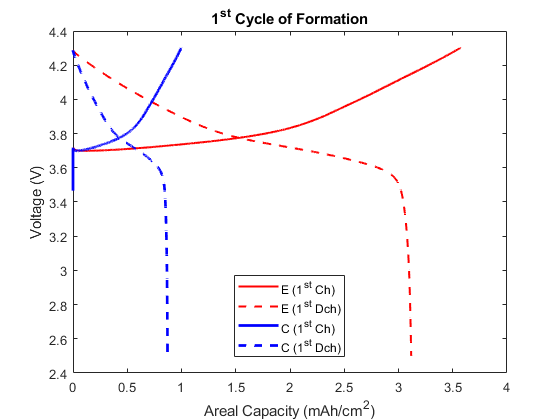

ExpCapch = Capch_c*x/MCapch_c; % to obtain the expanded capacity during 1st discharge
ExpCapdch = Capdch_c*x/MCapch_c; % to obtain the expanded capacity during 1st charge

plot(Capch_c,Volch_c,'r-','linewidth',1.5)
hold on
plot(Capdch_c,Voldch_c,'r--','linewidth',1.5)
plot(ExpCapch,Volch_c,'b-','linewidth',2) % plot the V vs. capacity(expanded) during during 1st charge 
plot(ExpCapdch,Voldch_c,'b--','linewidth',2) % plot the V vs. capacity(expanded) during during 1st discharge 

title('1^s^t Cycle of Formation')
xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
legend('E (1^s^t Ch)','E (1^s^t Dch)','C (1^s^t Ch)','C (1^s^t Dch)','location',"best")
hold off



% plot experimental and adjusted data for the second cycle
secondk = find(data.cycle_number==1 & data.ave_I_mA>0 ); % obtain the index for the second discharge
secondl = find(data.cycle_number==1 & data.ave_I_mA<0); % To find the second charge

secondVolch_c = data.Ecell_V(secondk(2:end)); % obtain the voltage in the second discharge
secondVoldch_c = data.Ecell_V(secondl); % obtain the voltage in the second charge
secondCapch_c= data.Capacity_mAh(secondk(2:end))/A

secondCapch_c =     0.0000
    0.0000
    0.0002
    0.0006
    0.0023
    0.0048
    0.0073
    0.0098
    0.0123
    0.0148


secondCapdch_c = data.Capacity_mAh(secondl)/A;
disp('Max capacity on 2st cycle charge and discharge in mAh/cm2')

Max capacity on 2st cycle charge and discharge in mAh/cm2



[M2ndCapch_c,idx2ndCapch] = max(secondCapch_c)

M2ndCapch_c = 3.2927

idx2ndCapch = 1327

[M2ndCapdch_c,idx2ndCapdch] = max(secondCapdch_c)

M2ndCapdch_c = 3.1445

idx2ndCapdch = 1394

ExpCap2ndch = secondCapch_c*x/M2ndCapch_c % to obtain the expanded capacity during 2nd discharge

ExpCap2ndch =     0.0000
    0.0000
    0.0000
    0.0002
    0.0007
    0.0015
    0.0022
    0.0030
    0.0037
    0.0045


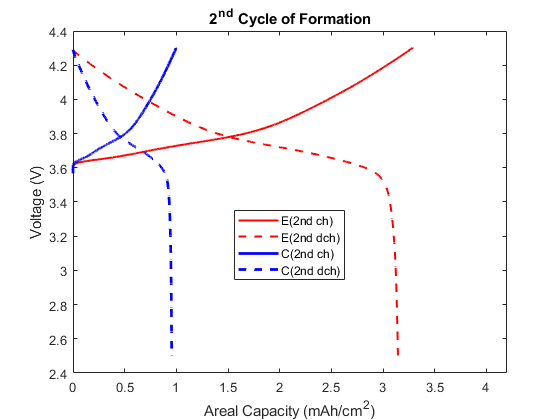

ExpCap2nddch = secondCapdch_c*x/M2ndCapch_c; % to obtain the expanded capacity during 2nd charge
save M2ndCapch_c;
save M2ndCapdch_c;
plot(secondCapch_c,secondVolch_c,'r-','linewidth',1.5)
hold on
plot(secondCapdch_c,secondVoldch_c,'r--','linewidth',1.5)
plot(ExpCap2ndch,secondVolch_c,'b-','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd discharge
plot(ExpCap2nddch,secondVoldch_c,'b--','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd charge

title('2^n^d Cycle of Formation')
xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
legend('E(2nd ch)','E(2nd dch)', 'C(2nd ch)','C(2nd dch)','location',"best")
hold off

xlim([0.00 4.200])
ylim([2.40 4.40])



% Create interp1 function to plot the interpolated profile of the first cycle
disp('get the interpolated values for voltage at different capacities for 2nd cycle')

get the interpolated values for voltage at different capacities for 2nd cycle


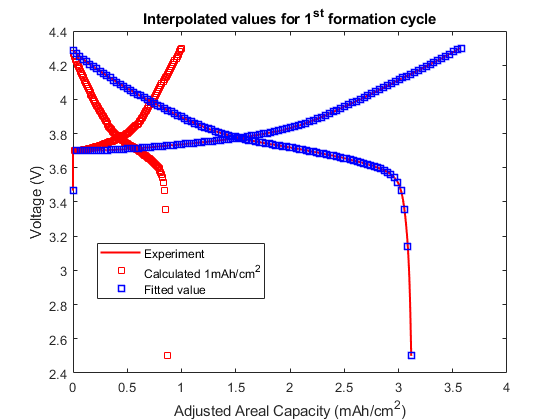

Z = 100;
C1_m = (0:max(ExpCapch)/Z:max(ExpCapch))'; % to get the 100 scatters axis for expand capacity in 1ch
C1_n = (0:max(ExpCapdch)/Z:max(ExpCapdch))'; % to get the 100 scatter axis for expand capacity in 1dch
C_Vxpch = interp1(ExpCapch,Volch_c,C1_m,'linear','extrap');% to get the 100 scatters axis for voltage in 1ch
C_Vxpdch = interp1(ExpCapdch,Voldch_c,C1_n,'linear','extrap');% to get the 100 scatters axis for voltage in 1dch
save C_Vxpch;
save C_Vxpdch;
h1=plot(Capch_c,Volch_c,'r-','linewidth',1.5);
hold on
h2=plot(Capdch_c,Voldch_c,'r-','linewidth',1.5);
h3=plot(C1_m,C_Vxpch,'rs');
h4=plot(C1_n,C_Vxpdch,'rs');
h5=plot(MCapch_c*C1_m,C_Vxpch,'bs','linewidth',1.5);
h6=plot(MCapch_c*C1_n,C_Vxpdch,'bs','linewidth',1.5);
xlabel('Adjusted Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
title('Interpolated values for 1^s^t formation cycle')
legend([h1,h3,h5],'Experiment','Calculated 1mAh/cm^2','Fitted value','location',"best")
hold off


save C1_m;
save C1_n;
save C_Vxpch-A_Vxpdch.mat;
save C_Vxpdch-A_Vxpch.mat;

% Create interp1 function to plot the interpolated profile of the second cycle
% 
disp('get the interpolated values for voltage at different capacities for 2nd cycle')

get the interpolated values for voltage at different capacities for 2nd cycle


Z = 100;
C2_m = (0:max(ExpCap2ndch)/Z:max(ExpCap2ndch))'

C2_m =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


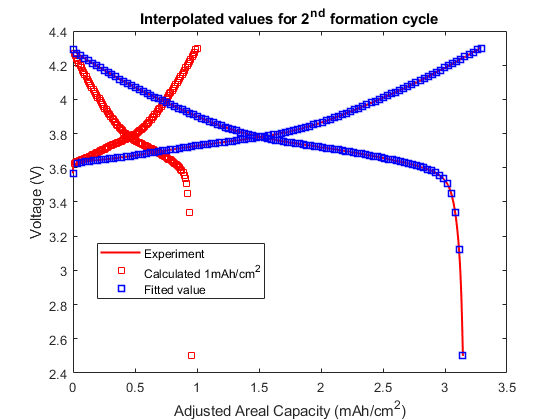

C2_n = (0:max(ExpCap2nddch)/Z:max(ExpCap2nddch))';
C_Vxp2ndch = interp1(ExpCap2ndch,secondVolch_c,C2_m,'linear','extrap');
C_Vxp2nddch = interp1(ExpCap2nddch,secondVoldch_c,C2_n,'linear','extrap');
save C_Vxp2ndch;
save C_Vxp2nddch;
h1=plot(secondCapch_c,secondVolch_c,'r-','linewidth',1.5);
hold on
h2=plot(secondCapdch_c,secondVoldch_c,'r-','linewidth',1.5);
h3=plot(C2_m,C_Vxp2ndch,'rs');
h4=plot(C2_n,C_Vxp2nddch,'rs');
h5=plot(M2ndCapch_c*C2_m,C_Vxp2ndch,'bs','linewidth',1.5);
h6=plot(M2ndCapch_c*C2_n,C_Vxp2nddch,'bs','linewidth',1.5);
xlabel('Adjusted Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
title('Interpolated values for 2^n^d formation cycle')
legend([h1,h3,h5],'Experiment','Calculated 1mAh/cm^2','Fitted value','location',"best")
hold off


save C2_m;
save C2_n;
save C_Vxp2ndch-A_Vxp2nddch.mat;
save C_Vxp2nddch-A_Vxp2ndch.mat;


**Section 3: Obtain the Stoichiometry**

disp 'To calculate the Stochoimetry with mol/mol method from Yongxiu'

To calculate the Stochoimetry with mol/mol method from Yongxiu


nlithium = m_NMC/M_NMC % mass/molar weight =mol, the overall mol of lithium in the electrode 

nlithium = 3.1773e-04

ncLi=MCapch_c*A*3.6/F

ncLi = 2.2961e-04


% to calculate the transfered lithium during first and second cycles
ntrans_Li_ch = Capch_c*A*3.6/F; % n=cap*3.6/F(C/mol)=mol,calcuate the transfer of lithium in the first discharge
ntrans_Li_dch = Capdch_c*A*3.6/F; % n=cap*area*3.6/F(C/mol)=mol,calcuate the transfer of lithium in the first charge
ntrans_Li_2ndch = secondCapch_c*A*3.6/F; % n=cap*3.6/F(C/mol)=mol,calcuate the transfer of lithium in the second discharge
ntrans_Li_2nddch = secondCapdch_c*A*3.6/F; % n=cap*3.6/F(C/mol)=mol,calcuate the transfer of lithium in the second charge

% to calculate the remaining lithium during first and second cycles
n_remain_Li_ch = nlithium-ntrans_Li_ch;  % remaining lithium in the first discharge
n_remain_Li_dch = min(n_remain_Li_ch)+ntrans_Li_dch;  % remaining lithium in the first charge
n_remain_Li_2ndch = max(n_remain_Li_dch)-ntrans_Li_2ndch; % remaining lithium in the second discharge
n_remain_Li_2nddch = min(n_remain_Li_2ndch)+ntrans_Li_2nddch; % remaining lithium in the second charge

% to calcuate the stoichiometry of cathode during first and second cycle
Sto_Li_ch = n_remain_Li_ch/nlithium;% stoichiometry change during the first dischagre
Sto_Li_dch = n_remain_Li_dch/nlithium; % stoichiometry change during the first chagre
Sto_Li_2ndch = n_remain_Li_2ndch/nlithium; % stoichiometry change during the 2nd dischagre
Sto_Li_2nddch = n_remain_Li_2nddch/nlithium; % stoichiometry change during the 2nd chagre

M1ch_Sto = max(Sto_Li_ch)

M1ch_Sto = 1.0000

M1dch_Sto=max(Sto_Li_dch)

M1dch_Sto = 0.9070

M2ch_Sto=max(Sto_Li_2ndch)

M2ch_Sto = 0.9070

M2dch_Sto=max(Sto_Li_2nddch)

M2dch_Sto = 0.8771

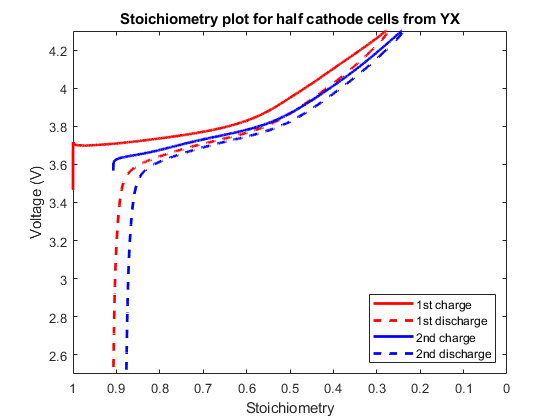


% to plot the Voltage vs. Stoichiometry during the fisrt and second cycles
plot(Sto_Li_ch,Volch_c,'r-','linewidth',2)
set(gca,'xDir','reverse')
hold on
plot(Sto_Li_dch,Voldch_c,'r--','linewidth',2)
hold on
% add the Voltage vs. Stoichiometry plot for the second cycle
plot(Sto_Li_2ndch,secondVolch_c,'b-','linewidth',2)
set(gca,'xDir','reverse')
hold on
plot(Sto_Li_2nddch,secondVoldch_c,'b--','linewidth',2)
% ax= xDir:'reverse' YDir:'reverse'
legend('1st charge','1st discharge','2nd charge','2nd discharge','location',"southeast")
xlabel('Stoichiometry')
ylabel('Voltage (V)')
title('Stoichiometry plot for half cathode cells from YX')
hold off
ylim([2.5 4.3])
xlim([0 1])



disp 'To calculate the Stochoimetry with (g/m2)/(g/m2) method from Emma'

To calculate the Stochoimetry with (g/m2)/(g/m2) method from Emma


% Sto=C(mol/m^3)*Vol_F(active material)*Thickness(m)*M_NMC(g/mol)/GSM(g/m^2)
% C=Cap(mAh)*3.6/A(m^2)/F/Thickness
Csmax_Li=49310.37684 % the theroical maximl lithium concentration in particle

Csmax_Li = 4.9310e+04

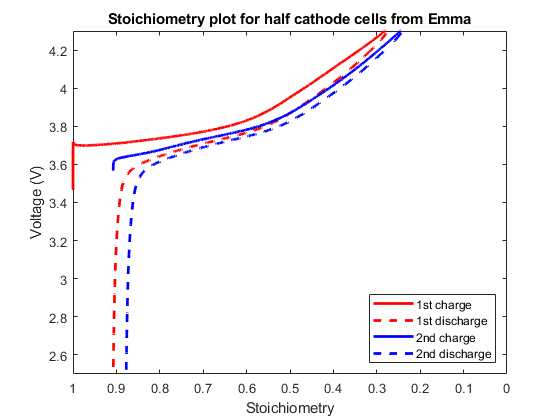

Q1ch=data.Q_Qo_mAh(k);
Q1dch=data.Q_Qo_mAh(l);
Q2ch=data.Q_Qo_mAh(secondk);
Q2dch=data.Q_Qo_mAh(secondl);

C1ch=(Q1ch/(A/10000))*3.6/F/Th_c/Vol_F;
C1dch=(Q1dch/(A/10000))*3.6/F/Th_c/Vol_F;
C2ch=(Q2ch/(A/10000))*3.6/F/Th_c/Vol_F;
C2dch=(Q2dch/(A/10000))*3.6/F/Th_c/Vol_F;

Sto_Li_ch_E=(Csmax_Li-C1ch)*Vol_F*Th_c*M_NMC/GSM_c;
Sto_Li_dch_E=(Csmax_Li-C1dch)*Vol_F*Th_c*M_NMC/GSM_c;
Sto_Li_2ch_E=(Csmax_Li-C2ch)*Vol_F*Th_c*M_NMC/GSM_c;
Sto_Li_2dch_E=(Csmax_Li-C2dch)*Vol_F*Th_c*M_NMC/GSM_c;

plot(Sto_Li_ch_E,Volch_c,'r-','linewidth',2)
set(gca,'xDir','reverse')
hold on
plot(Sto_Li_dch_E,Voldch_c,'r--','linewidth',2)
hold on
% add the Voltage vs. Stoichiometry plot for the second cycle
plot(Sto_Li_2ch_E(2:end),secondVolch_c,'b-','linewidth',2)
set(gca,'xDir','reverse')
hold on
plot(Sto_Li_2dch_E(1:end),secondVoldch_c,'b--','linewidth',2)
% ax= xDir:'reverse' YDir:'reverse'
legend('1st charge','1st discharge','2nd charge','2nd discharge','location',"southeast")
xlabel('Stoichiometry')
ylabel('Voltage (V)')
title('Stoichiometry plot for half cathode cells from Emma')
hold off
ylim([2.5 4.3])
xlim([0 1])

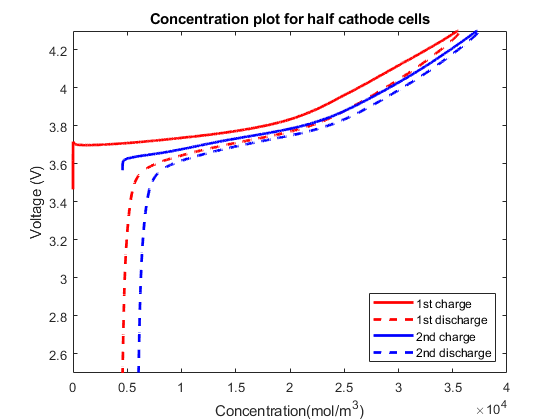


Sc_Vxp2ndch = interp1(ExpCap2ndch,Sto_Li_2ndch,C2_m,'linear','extrap');
Sc_Vxp2nddch = interp1(ExpCap2nddch,Sto_Li_2nddch,C2_n,'linear','extrap');
save Sc_Vxp2ndch;
save Sc_Vxp2nddch;

% to plot the voltage with concentration in the particle
plot(C1ch,Volch_c,'r-','linewidth',2)
%set(gca,'xDir','reverse')
hold on
plot(C1dch,Voldch_c,'r--','linewidth',2)
hold on
% add the Voltage vs. Stoichiometry plot for the second cycle
plot(C2ch(2:end),secondVolch_c,'b-','linewidth',2)
%set(gca,'xDir','reverse')
hold on
plot(C2dch,secondVoldch_c,'b--','linewidth',2)
% ax= xDir:'reverse' YDir:'reverse'
legend('1st charge','1st discharge','2nd charge','2nd discharge','location',"southeast")
xlabel('Concentration(mol/m^3)')
ylabel('Voltage (V)')
title('Concentration plot for half cathode cells')
hold off
ylim([2.5 4.3])

**Section 4: plot dQ/dV (adjusted with expansion factor)**

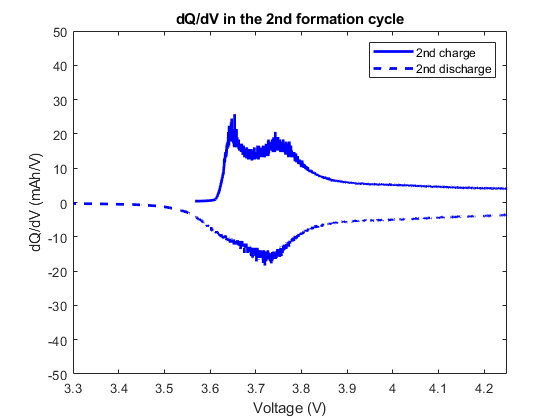


% To calculate dV and dQ in the second cycle
%Function for DVA and ICA to make the data smooth
MA = 25;  % span for moving average filter
% g = gausswin(100);  % 100 is the sample size for the gaussian window
% g value determines the width of the smoothing window.
%  If you have signal process toolbox uncomment above else use the expressions below, 
%  change the value of alpha.
N=100;
M= (N-1)/2;
alpha=2.5;
n= (-(N-1)/2:(N-1)/2)';
g= exp((-0.5)*((alpha^2 *n.^2)/(M^2)));
g = g/sum(g);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
B = 1:(size(secondVolch_c)-1);
deltaVm2ndch = secondVolch_c(B+1)-secondVolch_c(B);
deltaCapm2ndch = A*x*(secondCapdch_c(B+1)-secondCapdch_c(B));
DiffQV2ndch = smooth(deltaCapm2ndch)./smooth(deltaVm2ndch);
% DiffQV2ndch = deltaCapm2ndch./deltaVm2ndch;
plot(secondVolch_c(1:end-1),DiffQV2ndch,'b-','linewidth',2)
set(gca,'xDir','normal')
hold on
% To obtain the first discharge
C = 1:(size(secondVoldch_c)-1);
deltaVm2nddch = secondVoldch_c(C+1)-secondVoldch_c(C);
deltaCapm2nddch = A*x*(secondCapdch_c(C+1)-secondCapdch_c(C));
% To plot the dQ/dV in the second cycle
% plot(secondVoldch(2:end),deltaCapm2nddch./deltaVm2nddch,'b--','linewidth',2);
plot(secondVoldch_c(2:end),smooth(deltaCapm2nddch)./smooth(deltaVm2nddch),'b--','linewidth',2);
xlabel('Voltage (V)')
ylabel('dQ/dV (mAh/V)')
legend('2nd charge','2nd discharge')
title('dQ/dV in the 2nd formation cycle')
hold off
xlim([3.3 4.25])
ylim([-50 50])

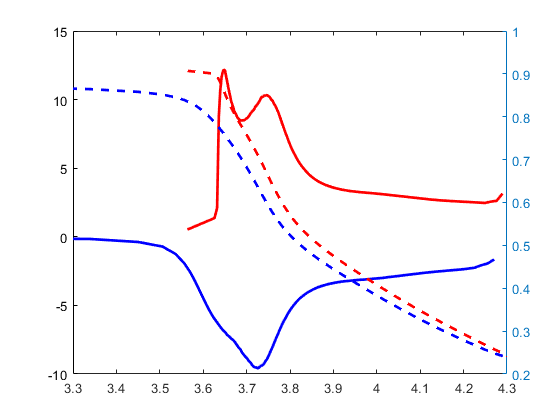


% to plot the dQ/dV from the interpolation and also the stochoimetry for
% the whole votage in second cycle
plot(C_Vxp2ndch(1:end-1),(M2ndCapch_c/max(C2_m))*smooth(diff(C2_m))./smooth(diff(C_Vxp2ndch)),'r-','linewidth',2)
hold on
plot(C_Vxp2nddch(2:end),(M2ndCapch_c/max(C2_n))*smooth(diff(C2_n))./smooth(diff(C_Vxp2nddch)),'b-','linewidth',2)
yyaxis right
plot(C_Vxp2ndch,Sc_Vxp2ndch,'r--','linewidth',2)
plot(C_Vxp2nddch,Sc_Vxp2nddch,'b--','linewidth',2)
hold off
xlim([3.3 4.3])
% ylim([-50 50])
hold off

Data_Cathode=[C_Vxp2ndch,Sc_Vxp2ndch,C_Vxp2nddch,Sc_Vxp2nddch];
Header_Data_Cathode = {'V at delithiation / V','Stochoimetry at delithiation','V at lithiation / V','Stochoimetry at lithiation'};
Data_Cathode=[Header_Data_Cathode;num2cell(Data_Cathode)]

Data_Cathode = 102×4 cell array
    {'V at delithiation / V'}    {'Stochoimetry at delithiation'}    {'V at lithiation / V'}    {'Stochoimetry at lithiation'}
    {[               3.5637]}    {[                      0.9070]}    {[             4.2905]}    {[                    0.2419]}
    {[               3.6261]}    {[                      0.9004]}    {[             4.2706]}    {[                    0.2482]}
    {[               3.6320]}    {[                      0.8937]}    {[             4.2550]}    {[                    0.2546]}
    {[               3.6360]}    {[                      0.8871]}    {[             4.2399]}    {[                    0.2609]}
    {[               3.6392]}    {[                      0.8804]}    {[             4.2255]}    {[                    0.2673]}
    {[               3.6422]}    {[                      0.8738]}    {[             4.2114]}    {[                    0.2736]}
    {[               3.6449]}    {[                      0.8671]}    {[        